% Imperial College London
% 2024-25 MRes in Medical Robotics and Instrumentation
% Coursework 01 - Coppelia Tester for Task 4
% Author: Hongyu Wang

clc;
close all;
clear;

## CoppeliaSim Using ZeroMQ

HOST = '127.0.0.1'; % CoppeliaSim IP
PORT = 23000;       % Port CoppeliaSim ZeroMQ is listening on

checkCoppeliaSimConnection(HOST, PORT, 3);

[LOG INFO] -- CoppeliaSim Can be Connected
[LOG INFO] -- CoppeliaSim IP Address 127.0.0.1


simClient = RemoteAPIClient();
fprintf('[LOG INFO] -- Connecting to CoppeliaSim...\n');

[LOG INFO] -- Connecting to CoppeliaSim...


coppelia = simClient.require('sim'); % Get the handle for CoppeliaSim API

% Start simulation
try
    coppelia.startSimulation();
    fprintf('[LOG INFO] -- Simulation started successfully.\n');
catch
    error('[WARNING] -- Failed to start simulation. Ensure CoppeliaSim is running.');
end

[LOG INFO] -- Simulation started successfully.


% Define joint names and end-effector name
joint_names = {'/Mirobot/joint1', '/Mirobot/joint2', '/Mirobot/joint3', ...
    '/Mirobot/joint4', '/Mirobot/joint5', '/Mirobot/joint6'};
ee_name = '/Mirobot/Tip';
cube_1_name = '/Cube1';
cube_2_name = '/Cube2';

% Get handles for joints and end-effector
joint_handles = zeros(length(joint_names), 1);
for i = 1:length(joint_names)
    joint_handles(i) = coppelia.getObject(joint_names{i});
end
ee_handle = coppelia.getObject(ee_name);
cube_1_handle = coppelia.getObject(cube_1_name);
cube_2_handle = coppelia.getObject(cube_2_name);
cube_handles = [cube_1_handle;cube_2_handle];

### Inverse Kinematics

config = initConfig();
robot = initRobot(config);


% MATLAB SPACE
% Define commands: [x, y, z, roll, pitch, yaw, gripper_status]
% Simulation parameters
ik = inverseKinematics("RigidBodyTree", robot);
weights = [1, 1, 1, 0.1, 0.1, 0.1];
initial_guess_coppelia = config.home_configuration_coppelia;

ref_offset = config.home_configuration_coppelia - config.home_configuration_matlab;


% Gripper_Status:    0-nothing 
%                   11-cube 1 catched;  10-cube 1 dropped
%                   21-cube 2 catched;  20-cube 2 dropped

% Commands (X, Y, Z in mm; RX, RY, RZ in degrees; Gripper_Status)

commands = [
%     X        Y        Z      RX      RY      RZ     Gripper_Status
    0.0,   198.6,   230.7,    0.0,    0.0,   90.0,    0;  % Start Position
   -1.5,   288.0,    69.8,    3.8,   -3.9,   87.4,   11;  % Cube 1 Pick Position
  211.4,     1.7,   234.4,  -32.1,    2.9,  102.6,    0;  % Intermediate Point
  213.0,  -146.9,   111.0,   -1.6,   -3.9,   67.3,    0;  % Intermediate Point
  251.6,   -60.8,   111.0,   -1.7,   -3.9,   88.4,   10;  % Cube 1 Place Position
  193.6,  -171.9,   111.0,   -1.7,   -3.9,   60.4,    0;  % Intermediate Point
  205.7,  -155.1,    91.4,  160.6,   74.2,   45.7,    0;  % Intermediate Point
  246.4,   -75.4,    91.4,  160.6,   74.2,   65.7,   21;  % Cube 2 Pick Position
  228.2,  -116.2,   171.2,  108.8,   64.2,    6.6,    0;  % Intermediate Point
  204.5,   154.1,   171.2,  108.8,   64.2,   70.6,    0;  % Intermediate Point
  221.1,   117.9,   157.8,   -3.7,   65.5,   78.5,    0;  % Intermediate Point
  241.1,   100.5,    66.6,   23.8,   92.2,  117.4,   20;  % Cube 2 Place Position
];

sample_rate = 0.005;

### HOME

% HOMEING
for i=1:6
    coppelia.setJointTargetPosition(joint_handles(i), config.home_configuration_coppelia(i));
end

% Simulate and record
[joint_positions, joint_velocities, tip_positions, time_stamps] = ...
    simulateMotionWithRecording(ik, commands, weights, initial_guess_coppelia, ref_offset, coppelia, joint_handles, ee_handle,cube_handles, sample_rate);

[LOG INFO] -- Starting Motion Simulation and Recording...
[LOG INFO] -- COMMAND 01 -- [0 198.6 230.7 0 0 90 0]
----
[LOG INFO] -- COMMAND 02 -- [-1.5 288 69.8 3.8 -3.9 87.4 11]
[LOG INFO] -- Gripper OPEN - Cube 1 Caught.
----
[LOG INFO] -- COMMAND 03 -- [211.4 1.7 234.4 -32.1 2.9 102.6 0]
----
[LOG INFO] -- COMMAND 04 -- [213 -146.9 111 -1.6 -3.9 67.3 0]
----
[LOG INFO] -- COMMAND 05 -- [251.6 -60.8 111 -1.7 -3.9 88.4 10]
[LOG INFO] -- Gripper OFF - Cube 1 Dropped.
----
[LOG INFO] -- COMMAND 06 -- [193.6 -171.9 111 -1.7 -3.9 60.4 0]
----
[LOG INFO] -- COMMAND 07 -- [205.7 -155.1 91.4 160.6 74.2 45.7 0]
----
[LOG INFO] -- COMMAND 08 -- [246.4 -75.4 91.4 160.6 74.2 65.7 21]
[LOG INFO] -- Gripper OPEN - Cube 2 Caught.
----
[LOG INFO] -- COMMAND 09 -- [228.2 -116.2 171.2 108.8 64.2 6.6 0]
----
[LOG INFO] -- COMMAND 10 -- [204.5 154.1 171.2 108.8 64.2 70.6 0]
----
[LOG INFO] -- COMMAND 11 -- [221.1 117.9 157.8 -3.7 65.5 78.5 0]
----
[LOG INFO] -- COMMAND 12 -- [241.1 100.5 66.6 23.8 92.2 11

coppelia.stopSimulation();

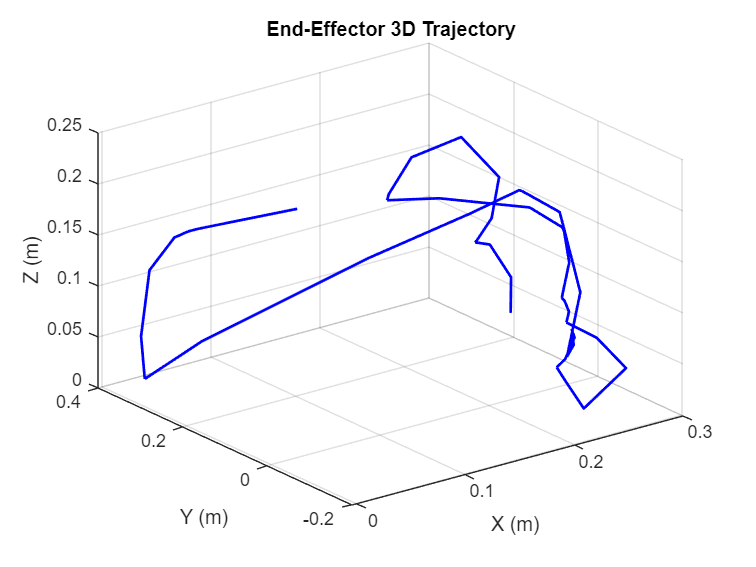

% Plot the 3D trajectory of the end-effector
figure;
plot3(tip_positions(2:end, 1), tip_positions(2:end, 2), tip_positions(2:end, 3), 'b-', 'LineWidth', 1.5);
xlabel('X (m)');
ylabel('Y (m)');
zlabel('Z (m)');
title('End-Effector 3D Trajectory');
grid on;

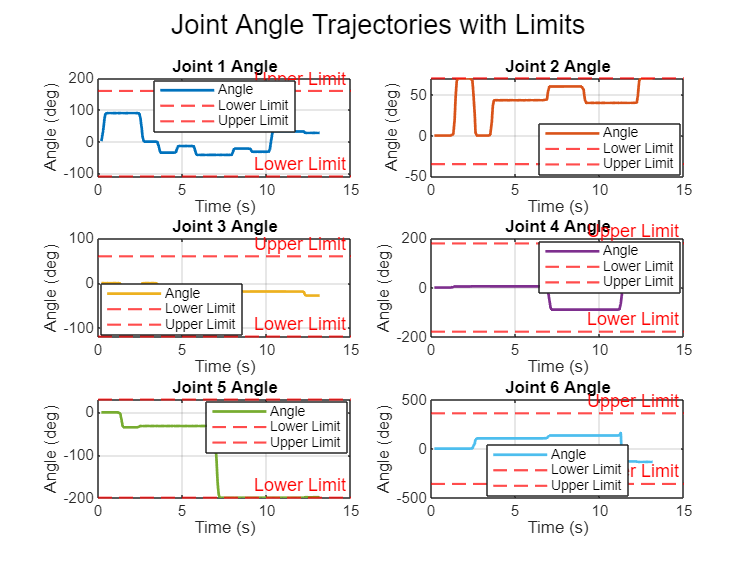

showJointAngleInTrajectory(joint_positions,config.joint_angle_limits_coppelia,time_stamps(1:2:end));

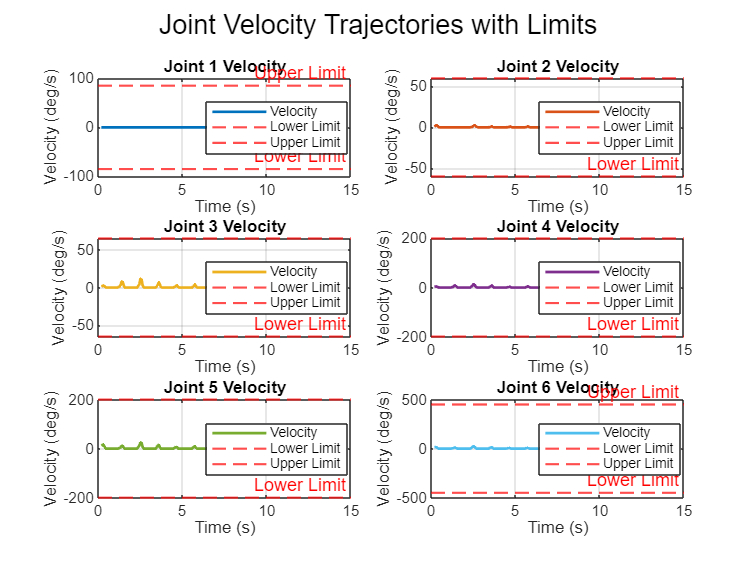

showJointVelocityInTrajectory(joint_velocities, config.joint_velocity_limits, time_stamps(1:2:end));